# Mechatronic Systems Identification Lab 1

## Mikołaj Suchoń

clear

fs = 500;
dt=1/fs;
N=500;
t=(0:N-1)*dt;
x1=1*sin(2*pi*t*30);
x2=2*sin(2*pi*t*30.5);
y=x1+x2;

Y = fft(y);

mag=abs(Y);

df=fs/N

df = 1

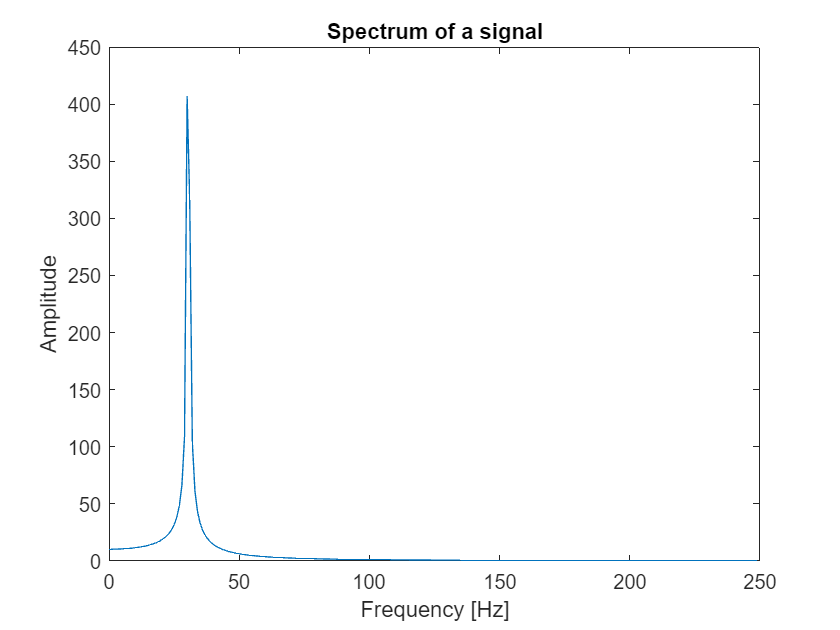

fv = (0:N-1)*df; % frequency vector
plot( fv(1:N/2) , mag(1:N/2))
title('Spectrum of a signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

Only one frequency is visible due to the spectral resolution being equal to 1 Hz

clear

fs = 500;
dt=1/fs;
% Necessary samples for 0.01 df:
N= fs/0.01

N = 50000



t=(0:N-1)*dt;
% t=0:dt:1-dt;

x1=1*sin(2*pi*t*30);
x2=2*sin(2*pi*t*30.5);

% plot(x1)
% 
y=x1+x2;

% plot(t,y)


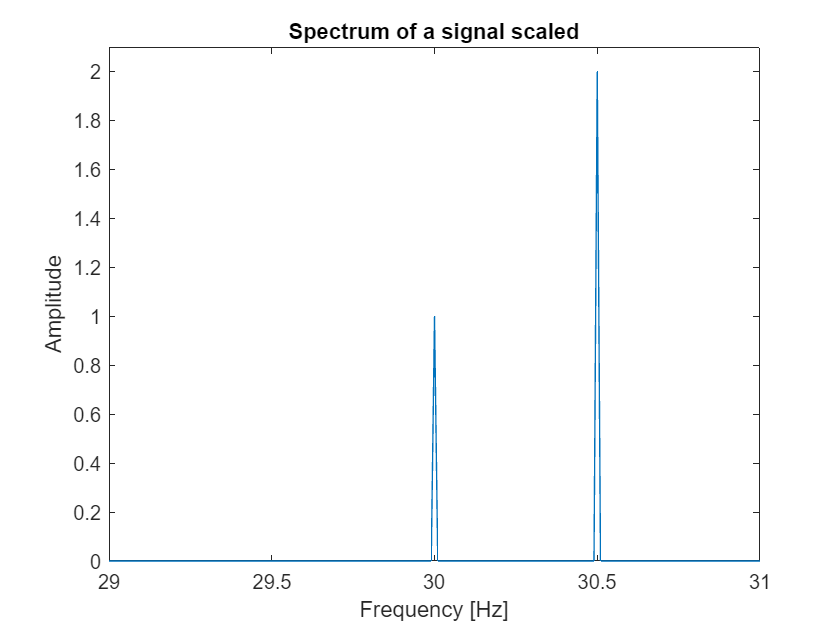

Y = fft(y);
% mag=abs(Y);
df=fs/N;
fv = (0:N-1)*df; % frequency vector
% plot( fv(1:N/2) , mag(1:N/2))
% title('Spectrum of a signal')
% xlabel('Frequency [Hz]')
% ylabel('Amplitude')
% xlim([29 31]);   % Limit x-axis from 20 Hz to 35 Hz
% Scale the FFT amplitude
Y_mag = abs(Y) / N;             % Normalize by number of points
Y_mag(2:end-1) = 2 * Y_mag(2:end-1); % Multiply by 2 (except DC and Nyquist)


plot(fv(1:N/2),Y_mag(1:N/2))
title('Spectrum of a signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
xlim([29 31]);   % Limit x-axis from 20 Hz to 35 Hz
ylim([0 2.1]);   % Limit y-axis from 0 to 2.1

The minimal length of the signal to distinguish a certain df (frequency domain resolution) is calculated by fs/N (sampling frequency divided by the number of samples). The only way to get better frequency resolution is to increace sample time.

clear

fs = 1000;
dt=1/fs;
N= 1000;
t=(0:N-1)*dt;
x1=1*sin(2*pi*t*125);
x2=1*sin(2*pi*t*375);
y=x1+x2;

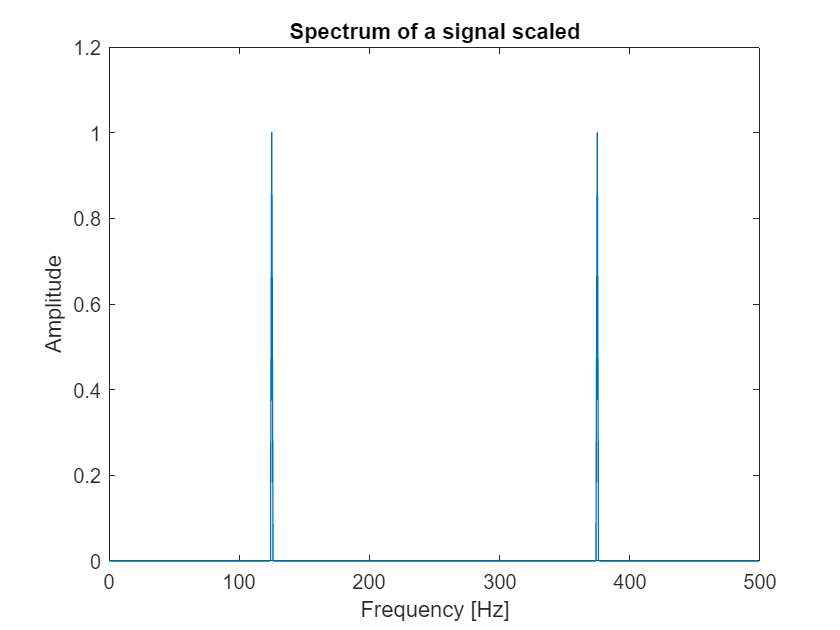

Y = fft(y);
mag=abs(Y);
df=fs/N;
fv = (0:N-1)*df; % frequency vector
% plot( fv(1:floor(N/2)) , mag(1:floor(N/2)))
% title('Spectrum of a signal')
% xlabel('Frequency [Hz]')
% ylabel('Amplitude')

% Scale the FFT amplitude
Y_mag = abs(Y) / N;             % Normalize by number of points
Y_mag(2:end-1) = 2 * Y_mag(2:end-1); % Multiply by 2 (except DC and Nyquist)

plot( fv(1:floor(N/2)) , Y_mag(1:floor(N/2)))
title('Spectrum of a signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

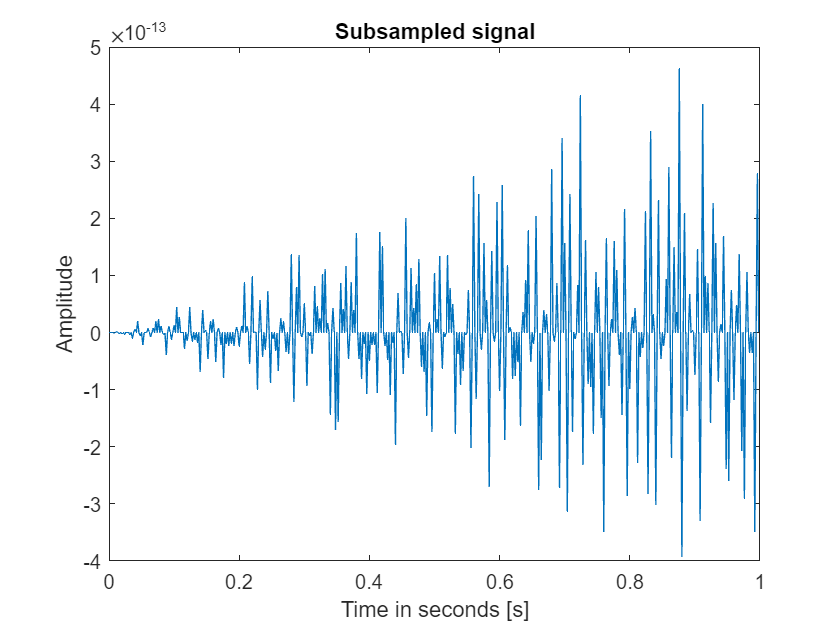

y_sub=y(1:2:end);
N2=length(y_sub);
fs2 = 1000/2;
dt2=1/fs2;
t2=(0:N2-1)*dt2;
plot(t2,y_sub)
title('Subsampled signal')
xlabel('Time in seconds [s]')
ylabel('Amplitude')

Here the signal disappears

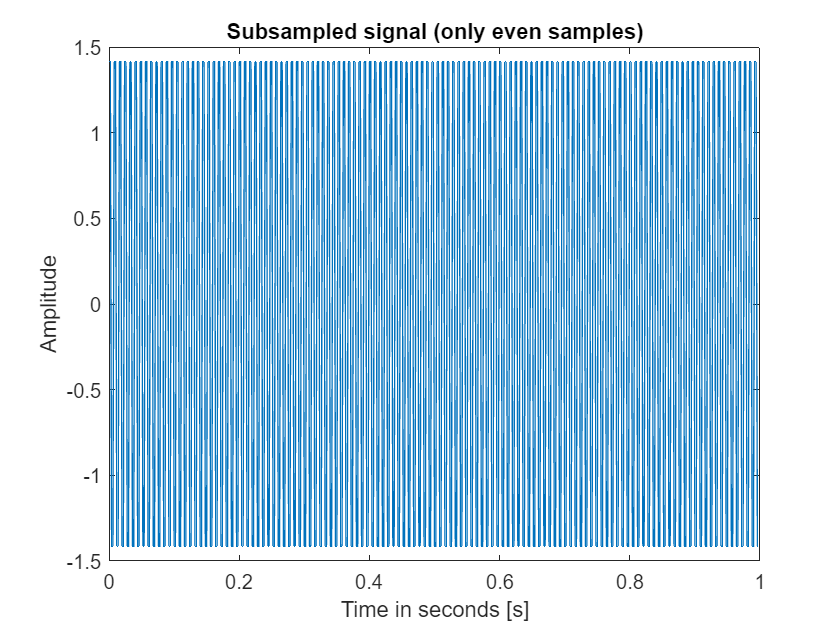

y_sub=y(2:2:end);
plot(t2,y_sub)
title('Subsampled signal (only even samples)')
xlabel('Time in seconds [s]')
ylabel('Amplitude')

Taking the even subsampled signal

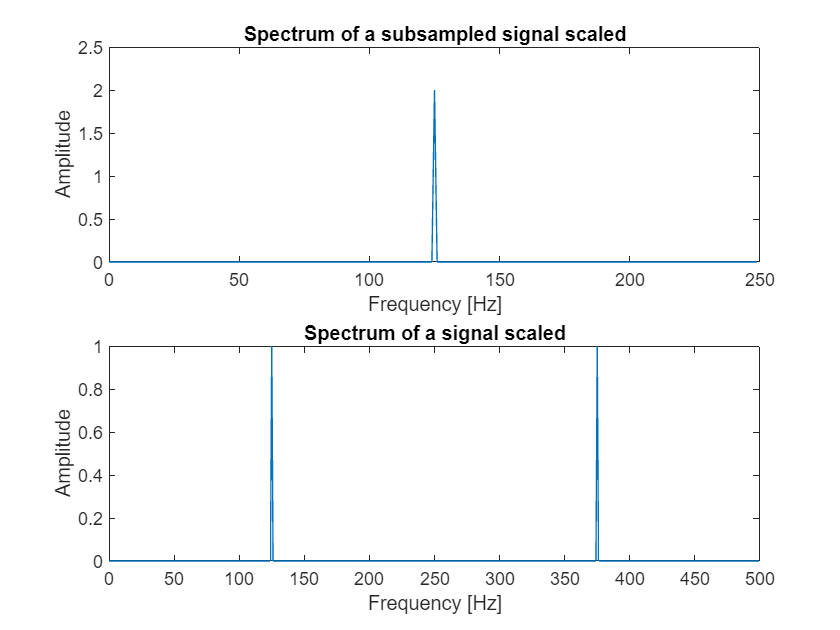

Y2 = fft(y_sub);
mag2=abs(Y2);
df2=fs2/N2;
fv2 = (0:N2-1)*df2;
% Scale the FFT amplitude
Y_mag2 = abs(Y2) / N2;             % Normalize by number of points
Y_mag2(2:end-1) = 2 * Y_mag2(2:end-1); % Multiply by 2 (except DC and Nyquist)
figure
subplot(2,1,1)
plot( fv2(1:floor(N2/2)) , Y_mag2(1:floor(N2/2)))
title('Spectrum of a subsampled signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
subplot(2,1,2)
plot( fv(1:floor(N/2)) , Y_mag(1:floor(N/2)))
title('Spectrum of a signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

We can observe, first, that the nyquist frequency is halved. Because the sin of 375 Hz gets added to the 125 Hz od the subsampled spectrum due to aliasing, the amplitude of the subsampled signal at frequency 125 Hz is the sum of amplitudes of frequencies 125 and 375 in the properly sampled signal.

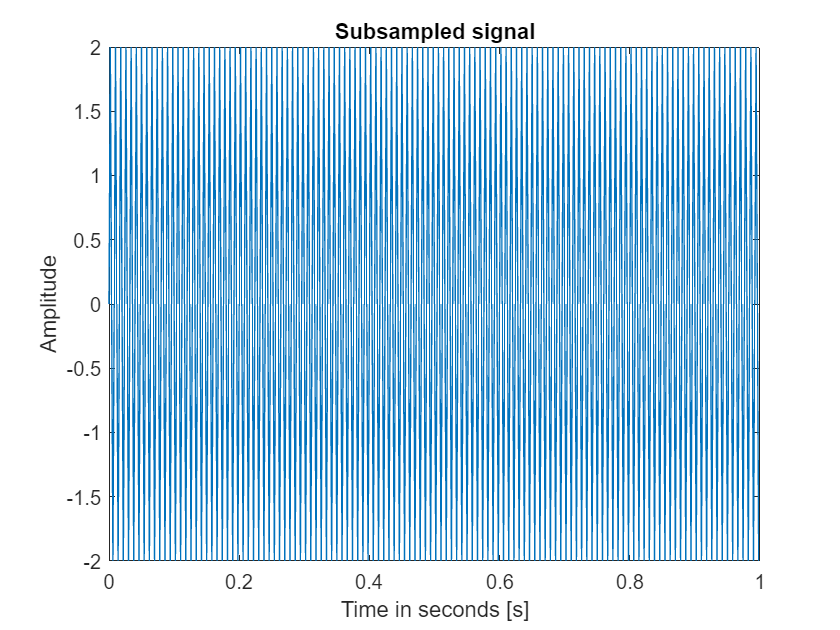

clear
fs = 1000;
dt=1/fs;
N= 1000;
t=(0:N-1)*dt;
x1=1*sin(2*pi*t*125);
x2=1*sin(2*pi*t*375);
y=x1-x2;

Y = fft(y);
mag=abs(Y);
df=fs/N;
fv = (0:N-1)*df;
% Scale the FFT amplitude
Y_mag = abs(Y) / N;             % Normalize by number of points
Y_mag(2:end-1) = 2 * Y_mag(2:end-1); % Multiply by 2 (except DC and Nyquist)

y_sub=y(1:2:end);
N2=length(y_sub);
fs2 = 1000/2;
dt2=1/fs2;
t2=(0:N2-1)*dt2;
figure
plot(t2,y_sub)
title('Subsampled signal')
xlabel('Time in seconds [s]')
ylabel('Amplitude')

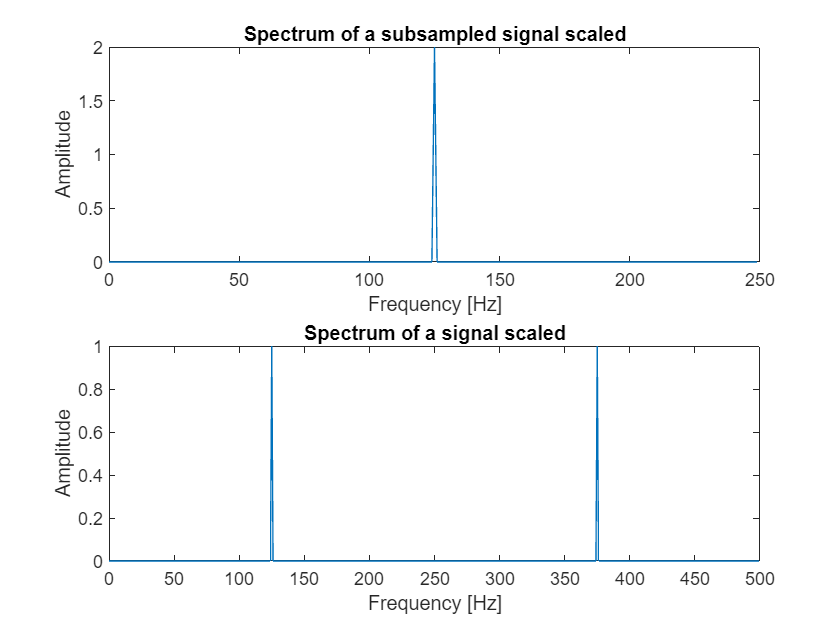

Y2 = fft(y_sub);
df2=fs2/N2;
fv2 = (0:N2-1)*df2;

% Scale the FFT amplitude
Y_mag2 = abs(Y2) / N2;             % Normalize by number of points
Y_mag2(2:end-1) = 2 * Y_mag2(2:end-1); % Multiply by 2 (except DC and Nyquist)
figure
subplot(2,1,1)
plot( fv2(1:floor(N2/2)) , Y_mag2(1:floor(N2/2)))
title('Spectrum of a subsampled signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')
subplot(2,1,2)
plot( fv(1:floor(N/2)) , Y_mag(1:floor(N/2)))
title('Spectrum of a signal scaled')
xlabel('Frequency [Hz]')
ylabel('Amplitude')

The conclusions from the comparison of signal subsampled for even samples and the original signal are the same for this section where a signal constructed from the difference of two sine waves was used.

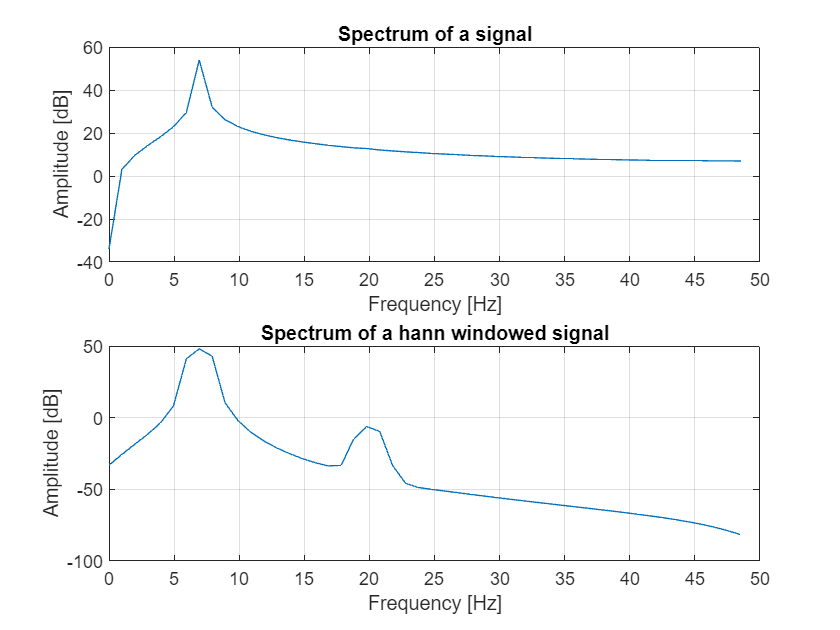

clear

fs=100;
dt=1/fs;
t=0:dt:1;
N=length(t);
x1=10*sin(2*pi*t*7);
x2=0.02*cos(2*pi*t*20);
y1=x1+x2;
Y1=fft(y1);
mag1=abs(Y1);
df=fs/N;
fv = (0:N-1)*df; % frequency vector
figure
subplot(2,1,1)
plot( fv(1:floor(N/2)) , 20*log10(mag1(1:floor(N/2))))
title('Spectrum of a signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
grid on;

w = hann(N, 'periodic')';       % Create a Hann window
y2 = y1 .* w;       % Multiply signal by window
Y2=fft(y2);
mag2=abs(Y2);

subplot(2,1,2)
plot( fv(1:floor(N/2)) , 20*log10(mag2(1:floor(N/2))))
title('Spectrum of a hann windowed signal')
xlabel('Frequency [Hz]')
ylabel('Amplitude [dB]')
grid on;

The spectrum of the original (unwindowed) signal has sharp peaks but suffers from spectral leakage, causing energy to spread into neighboring frequencies. The spectrum of  Hann-windowed signal reduces this leakage by tapering the signal edges, resulting in lower side lobes. However, the main lobe in the second signal is slightly wider, meaning frequency resolution is reduced compared to the unwindowed signal. Overall, y2 provides a cleaner frequency representation at the cost of minor amplitude attenuation and resolution loss.

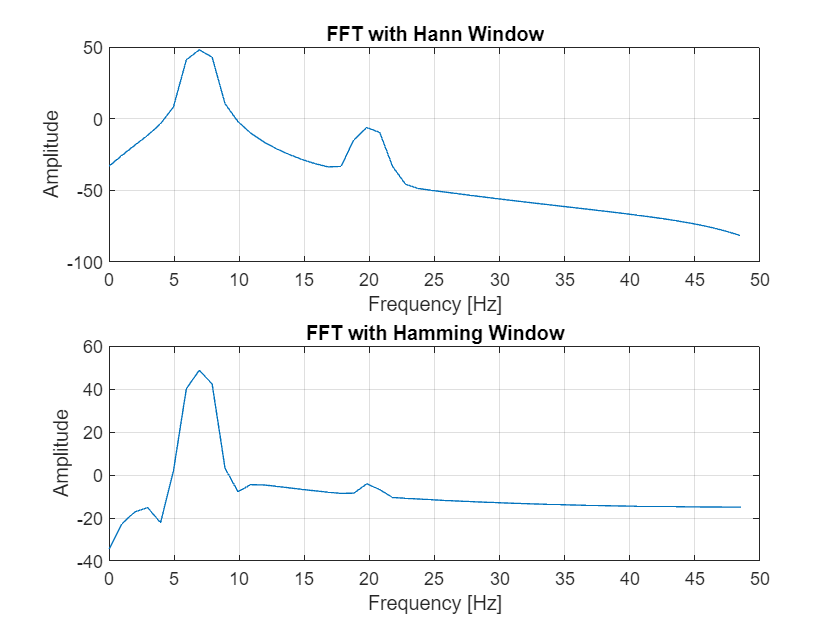


% Apply a Hamming window (y3)
hamming_window = hamming(N, 'periodic'); 
y3 = y1 .* hamming_window';

% Compute FFTs
Y3 = fft(y3);

mag3=abs(Y3);

subplot(2,1,1);
plot(fv(1:floor(N/2)), 20*log10(mag2(1:floor(N/2))));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('FFT with Hann Window');
grid on;

subplot(2,1,2);
plot(fv(1:floor(N/2)), 20*log10(mag3(1:floor(N/2))));
xlabel('Frequency [Hz]');
ylabel('Amplitude');
title('FFT with Hamming Window');
grid on;

The differences between the spectra of all signals are caused by the windowing functions applied to �unwindowed signal. The unwindowed signal has sharp transitions at the edges, leading to spectral leakage due to the FFT assuming periodicity. Windowed signals like� y2 (Hann) and y3� (Hamming) taper the signal smoothly to zero, reducing leakage but widening the main lobe, affecting frequency resolution. The specific window shape determines the tradeoff between resolution and leakage suppression, with Hamming reducing leakage more than Hann but slightly distorting amplitude.